clc; clear; close all;
L = 1200; % bridge length
n = 1200; % subsections of L
P = 400; % total weight of train
x = linspace(0, L, n+1); % x-axis for SFD & BMD


x_train = [52 228 392 568 732 908]; % train load locations (wheels)
P_train = [1 1 1 1 1 1] * -P/6; % load for each point

n_train = 1200; % num of train locations

Wi = zeros(n_train, n+1); %applied load
SFDi = zeros(n_train, n+1); % a SFD for each train location
BMDi = zeros(n_train, n+1); % same as above but BMD

for i = 1:n_train
    traincmloc = 1200/(n_train+1) * i; % place center of train at even spots along the bridge 
    flocs = x_train - (480-traincmloc); % make array of force locations
    temp_P_train = P_train; % copy force loads

    for j = 1:6
        if flocs(j) < 0 || flocs(j) > 1200 % check if any force locations are off bridge
            temp_P_train(j) = 0; % if so make force = 0
            
        end
    end

    By = sum(temp_P_train .* flocs) / -L; % solve for By with sum of moments from left
    Ay = -sum(temp_P_train) - By; % solve for Ay by Fy = 0

    Wi(i, 1) = Ay; % add support
    Wi(i, n+1) = By; % add support

    for j = 1:length(flocs) 
        if flocs(j) <= L && flocs(j) >= 0 % make sure is on bridge
            [~, idx] = min(abs(x - flocs(j)));
            Wi(i, idx) = temp_P_train(j);
        end
    end
    
    SFDi(i, :) = cumsum(Wi(i, :)); % calculate SFD
    BMDi(i, :) = cumsum(SFDi(i, :)); % calculate BMD



   %figure; plot(Wi(i, :)) % plot FBD
   %figure; plot(SFDi(i, :)) % plot SFD
   %figure; plot(BMDi(i, :)) % plot BMD

end

SFD = max(abs(SFDi)); % SFD envelope
SFD_for_graphing = max(SFDi)

SFD_for_graphing =   257.1191  256.7860  256.4530  256.1199  255.7868  255.4538  255.1207  254.7877  254.4546  254.1216  253.7885  253.4555  253.1224  252.7893  252.4563  252.1232  251.7902  251.4571  251.1241  250.7910  250.4580  250.1249  249.7918  249.4588  249.1257  248.7927  248.4596  248.1266  247.7935  247.4604  247.1274  246.7943  246.4613  246.1282  245.7952  245.4621  245.1291  244.7960  244.4629  244.1299  243.7968  243.4638  243.1307  242.7977  242.4646  242.1316  241.7985  241.4654  241.1324  240.7993


BMD = max(BMDi); % BMD envelope

%figure; plot(SFD(1, :))
%figure; plot(BMD(1, :))

% Bridge Parameters

% xc = location of cross-section change
% Btf = top flange width
% Ttf = top flange thickness (height)
% Bgt = glue tab width
% Tgt = glue tab thickness
% Bst = sides width 
% Tst = sides thickness (in original this is 75 - 1.27)
% Bb = bottom width
% Tb = bottom thickness



% = xc, Btf, Ttf, Bgt, Tgt, Bst, Tst, Bb, Tb 

% default: param = [0, 100, 1.27, 5, 1.27, 1.27, 73.73, 80, 1.27]
param = [0, 100, 1.27, 5, 1.27, 1.27, 73.73, 80, 1.27]

param =          0  100.0000    1.2700    5.0000    1.2700    1.2700   73.7300   80.0000    1.2700



number_of_webs = 4

number_of_webs = 4

% assuming webs are placed evenly

areas_of_param = [param(2)*param(3), param(4)*param(5), param(4)*param(5), param(6)*param(7), param(6)*param(7), param(8)*param(9)]

areas_of_param =   127.0000    6.3500    6.3500   93.6371   93.6371  101.6000


y_values_from_bot = [param(7)+param(9)+param(3)/2, param(7)+param(9)-param(5)/2, param(7)+param(9)-param(5)/2, param(9) + param(7)/2, param(9) + param(7)/2, param(9)/2]

y_values_from_bot =    75.6350   74.3650   74.3650   38.1350   38.1350    0.6350




% bft = interp1(param(:,1), param(:,2), x)



% y value of centriodal axis
ybar = sum(areas_of_param .* y_values_from_bot) / sum(areas_of_param)

ybar = 41.4311


% calculate I with parallel axis thereom (note the + Ad^2 functions could
% be wrong but I'm returning the correct value for design 0 so

I = (param(2)*param(3)^3)/12 + 2 * (param(4)*param(5)^3)/12 + 2*(param(6)*param(7)^3)/12 + (param(8)*param(9)^3)/12 + sum(areas_of_param .* (ybar - y_values_from_bot).^2)

I = 4.1835e+05


%assuming that the centroid is never below the top of the bottom bar (which
%likely should be the case)

%calculate Q's
Qcent = areas_of_param(6) * (ybar - y_values_from_bot(6)) + 2 * param(6)*(ybar - param(9))*(ybar - param(9))/2

Qcent = 6.1933e+03


Qglue = areas_of_param(1) * (y_values_from_bot(1) - ybar)

Qglue = 4.3439e+03


M = max(BMD)

M = 6.9545e+04


V = max(SFD)

V = 257.1191


%calculate flexural stresses and shear stresses

Flexural_Stress_Top = M*(param(9)+param(7)+param(3)-ybar)/I

Flexural_Stress_Top = 5.7914


Flexural_Stress_Bot = M*(ybar)/I

Flexural_Stress_Bot = 6.8873


Shear_Stress_Max = V*Qcent/(I*2*param(6))

Shear_Stress_Max = 1.4986


Shear_Stress_Glue = V*Qglue/(I*2*(param(4)+param(6)))

Shear_Stress_Glue = 0.2129


% initialize material variables
E = 4000;
mu = 0.2;
S_tens = 30;
S_comp = 6;
T_max = 4;
T_glue = 2;

% calculate maximum buckling stresses based on geometry

S_buck1 = 4*(pi^2)*E/(12*(1-mu^2))*(param(3)/param(8))^2

S_buck1 = 3.4546

S_buck2 = 0.4254*(pi^2)*E/(12*(1-mu^2))*(param(3)/((param(2)-param(8))/2))^2

S_buck2 = 23.5132

S_buck3 = 6*(pi^2)*E/(12*(1-mu^2))*(param(6)/(param(7)+param(9)-ybar))^2

S_buck3 = 29.4301

T_buck = 5*(pi^2)*E/(12*(1-mu^2))*((param(6)/param(7))^2+(param(6)/(L/(number_of_webs-1)))^2)

T_buck = 5.2566


% report out FOS

FOS_tension = S_tens / Flexural_Stress_Bot

FOS_tension = 4.3558

FOS_compression = S_comp / Flexural_Stress_Top

FOS_compression = 1.0360

FOS_buck1 = S_buck1 / Flexural_Stress_Top % top flange mid buckling

FOS_buck1 = 0.5965

FOS_buck2 = S_buck2 / Flexural_Stress_Top % top flange sides buckling

FOS_buck2 = 4.0600

FOS_buck3 = S_buck3 / Flexural_Stress_Top

FOS_buck3 = 5.0817

FOS_shear = T_max / Shear_Stress_Max

FOS_shear = 2.6692

FOS_glue = T_glue / Shear_Stress_Glue

FOS_glue = 9.3941

FOS_shear_buck = T_buck / Shear_Stress_Max

FOS_shear_buck = 3.5077


FOS = [FOS_tension FOS_compression FOS_shear FOS_glue FOS_buck1 FOS_buck2 FOS_buck3 FOS_shear_buck];
FOSindex = ["FOS_tension" "FOS_compression" "FOS_shear" "FOS_glue" "FOS_buck1" "FOS_buck2" "FOS_buck3" "FOS_shear_buck"];

% find lowest FOS and failure and print it out

[minFOS, index] = min(FOS);
minFOS

minFOS = 0.5965

Pf = minFOS*max(SFD)

Pf = 153.3707

reason = FOSindex(index)

reason = "FOS_buck1"


% find failure loads for all types for graphing

Mf_tens = FOS_tension * M

Mf_tens = 3.0293e+05

Mf_comp = FOS_compression * M

Mf_comp = 7.2049e+04

Mf_buck1 = FOS_buck1 * M

Mf_buck1 = 4.1483e+04

Mf_buck2 = FOS_buck2 * M

Mf_buck2 = 2.8235e+05

Mf_buck3 = FOS_buck3 * M

Mf_buck3 = 3.5340e+05


Vf_shear = FOS_shear * V

Vf_shear = 686.3013

Vf_glue = FOS_glue * V

Vf_glue = 2.4154e+03

Vf_buck = FOS_shear_buck * V

Vf_buck = 901.9063

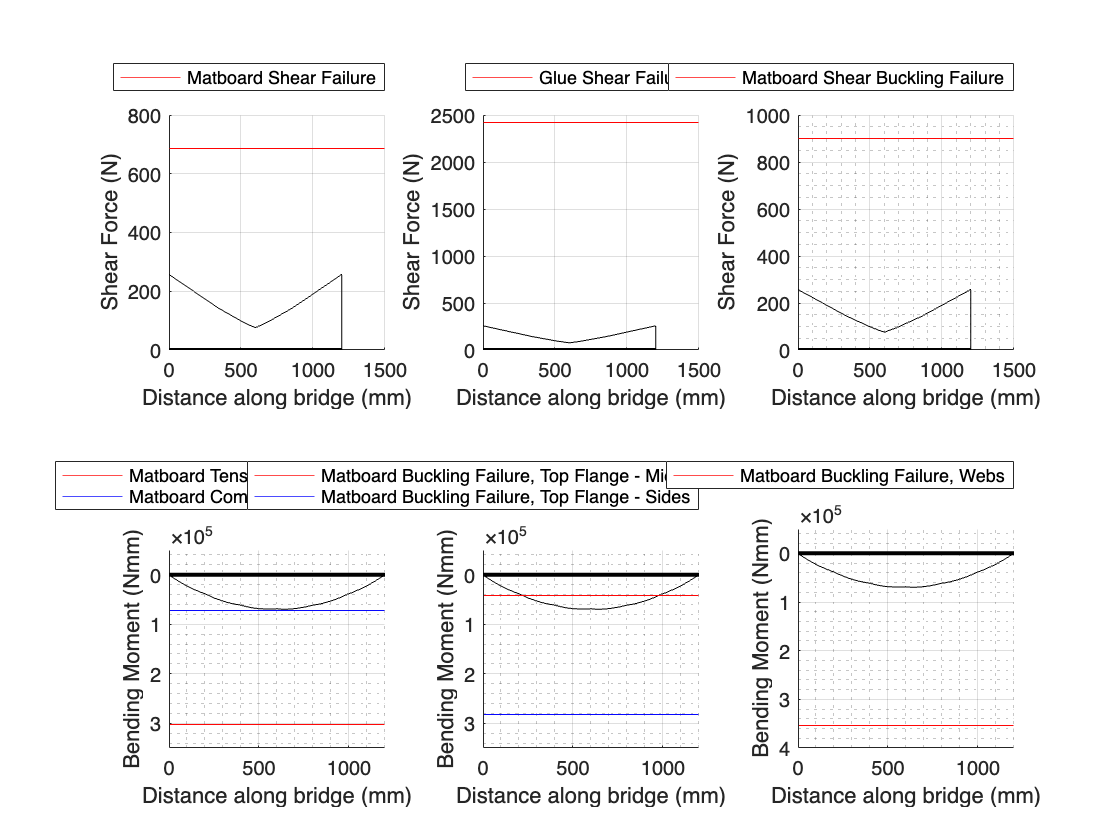


%graph plots

subplot(2,3,1)
hold on; grid on; grid minor;
yline(Vf_shear, "r")
plot(x, SFD, 'k');
plot([0, 1200], [0,0],'k','LineWidth',2)
legend("Matboard Shear Failure", 'Location', 'northoutside', 'Orientation', 'vertical')
xlabel("Distance along bridge (mm)")
ylabel("Shear Force (N)")

subplot(2,3,2)
hold on; grid on;, grid minor;
yline(Vf_glue, "r")
plot(x, SFD, 'k');
plot([0,1200],[0,0],'k','LineWidth',2)
legend("Glue Shear Failure", 'Location', 'northoutside', 'Orientation', 'vertical')
xlabel("Distance along bridge (mm)")
ylabel("Shear Force (N)")

subplot(2,3,3)
hold on; grid on; grid minor;
yline(Vf_buck, "r")
plot(x, SFD, 'k');
plot([0, 1200], [0,0],'k','LineWidth',2)
legend("Matboard Shear Buckling Failure", 'Location', 'northoutside', 'Orientation', 'vertical')
xlabel("Distance along bridge (mm)")
ylabel("Shear Force (N)")

subplot(2,3,4)
hold on; grid on; grid minor;
set(gca, 'Ydir','reverse')
axis([0 1200 (-0.5 * 10^5) (3.5*10^5)])
yline(Mf_tens, "r")
yline(Mf_comp, "b")
plot(x, BMD, 'k');
plot([0, 1200], [0,0],'k','LineWidth',2)
legend("Matboard Tension Failure", "Matboard Compression Failure", 'Location', 'northoutside', 'Orientation', 'vertical')
xlabel("Distance along bridge (mm)")
ylabel("Bending Moment (Nmm)")

subplot(2,3,5)
hold on; grid on; grid minor;
set(gca, 'Ydir','reverse')
axis([0 1200 (-0.5 * 10^5) (3.5*10^5)])
yline(Mf_buck1, "r")
yline(Mf_buck2, "b")
plot(x, BMD, 'k');
plot([0, 1200], [0,0],'k','LineWidth',2)
legend("Matboard Buckling Failure, Top Flange - Mid", "Matboard Buckling Failure, Top Flange - Sides", 'Location', 'northoutside', 'Orientation', 'vertical')
xlabel("Distance along bridge (mm)")
ylabel("Bending Moment (Nmm)")

subplot(2,3,6)
hold on; grid on; grid minor;
set(gca, 'Ydir','reverse')
axis([0 1200 (-0.5 * 10^5) (4*10^5)])
yline(Mf_buck3, "r")
plot(x, BMD, 'k');
plot([0, 1200], [0,0],'k','LineWidth',2)
legend("Matboard Buckling Failure, Webs", 'Location', 'northoutside', 'Orientation', 'vertical')
xlabel("Distance along bridge (mm)")
ylabel("Bending Moment (Nmm)")